## Feb 2022 Dataset

test_project_path = "feb_2022/planar_arm_2in";
tag_ids = [6 7 8 9];

g_tags = repmat({eye(3)}, 1, 4);

% the muscles that these muscles are attached to (in the same order) 
muscle_ids = [1 1 1 1]; % List of muscle ids that the tags are attached to, in order

% Define t_tags: Percentage of tag position along total length of arm
% Tag in the middle of arm: t = 0.5
muscle_length_cm = 18 * 2.54;
muscle_spacing_cm = 13;
base_offset_cm = 2;
t_tags = ([0, 1, 2, 3] * muscle_spacing_cm + base_offset_cm) / muscle_length_cm;

tags = Tag(tag_ids, {}, muscle_ids, t_tags, "group", SE2());

arm_obj = create_arm_obj(2, 2);

g_tag_offset = SE2.hat([0 0 -pi/2]);

dataset_params_feb_2in = DatasetParams("Planar 2 Inch (Old)", SE2, arm_obj, tags(1), tags, g_tag_offset);
dataset_params_feb_2in.f_parse_bag = @(bag_name) DatasetParams.parse_bag_generic(bag_name, 2, 2);
feb_2in = Dataset(test_project_path, dataset_params_feb_2in);

## April 2022 Datasts

tag_ids = [6 7 8 9 10 11 14];

% the muscles that these muscles are attached to (in the same order) 
muscle_ids = [1 1 1 2 2 2 2]; % List of muscle ids that the tags are attached to, in order

% Define t_tags: Percentage of tag position along total length of arm
% Tag in the middle of arm: t = 0.5
muscle_length_cm = 18 * 2.54;
base_offset_cm = 3;

posns_tags_left = [13, 25.5, 39]; % centimeters
posns_tags_right = [0, posns_tags_left];
t_tags = ([posns_tags_left, posns_tags_right] + base_offset_cm) / muscle_length_cm;

tags = Tag(tag_ids, {}, muscle_ids, t_tags, "group", SE2());
base_tag = tags([tags.id] == 9);

arm_obj_2in = create_arm_obj(2);

g_tag_offset = SE2.hat([0 0 0]);

dataset_params_apr = DatasetParams("2 inch #1", SE2, arm_obj_2in, base_tag, tags, g_tag_offset);
dataset_params_apr.f_parse_bag = @(bag_name) DatasetParams.parse_bag_generic(bag_name, 2, 1);
arm_2in_1 = Dataset("apr_2022/planar_arm_2in_4_23", dataset_params_apr);
dataset_params.dataset_name = "2 inch #2";
arm_2in_2 = Dataset("apr_2022/planar_arm_2in_4_25", dataset_params_apr);

dataset_params_apr.arm_obj = create_arm_obj(3);
dataset_params_apr.dataset_name = "3 inch #1";
arm_3in_1 = Dataset("apr_2022/planar_arm_3in_4_25", dataset_params_apr);
dataset_params_apr.dataset_name = "3 inch #2";
arm_3in_2 = Dataset("apr_2022/planar_arm_3in_4_30", dataset_params_apr);
dataset_params_apr.dataset_name = "3 inch #3";
arm_3in_3 = Dataset("apr_2022/planar_arm_3in_5_2", dataset_params_apr);

dataset_params_apr.arm_obj = create_arm_obj(4);
dataset_params_apr.dataset_name = "4 inch #1";
arm_4in_1 = Dataset("apr_2022/planar_arm_4in_4_25", dataset_params_apr);
dataset_params_apr.dataset_name = "4 inch #2"
arm_4in_2 = Dataset("apr_2022/planar_arm_4in_4_30", dataset_params_apr);
dataset_params_apr.dataset_name = "4 inch #3"
arm_4in_3 = Dataset("apr_2022/planar_arm_4in_4_30_2", dataset_params_apr);

dataset_params_apr.dataset_name = "4 inch #4";
tag_9_t_old = dataset_params_apr.tags([dataset_params_apr.tags.id] == 9).t;
dataset_params_apr.tags([dataset_params_apr.tags.id] == 9).t = dataset_params_apr.tags([dataset_params_apr.tags.id] == 10).t;
dataset_params_apr.tags([dataset_params_apr.tags.id] == 10).t = tag_9_t_old;
dataset_params_apr.base_tag = dataset_params_apr.tags([dataset_params_apr.tags.id] == 10);
arm_4in_4 = Dataset("apr_2022/planar_arm_4in_5_4", dataset_params_apr);

feb_2in.plot_dataset_curvature(axes(figure()));

figure()
set(gcf, "Position", [0, 0, 1600 400]);
subplot(1, 2, 1)
arm_2in_1.plot_dataset_curvature(gca);
subplot(1, 2, 2)
arm_2in_2.plot_dataset_curvature(gca);

figure()
set(gcf, "Position", [0, 0, 1600, 400]);
subplot(1, 3, 1)
arm_3in_1.plot_dataset_curvature(gca);
subplot(1, 3, 2)
arm_3in_2.plot_dataset_curvature(gca);
subplot(1, 3, 3)
arm_3in_3.plot_dataset_curvature(gca);

figure()
set(gcf, "Position", [0, 0, 1600, 400])
subplot(1, 4, 1)
arm_4in_1.plot_dataset_curvature(gca);
subplot(1, 4, 2);
arm_4in_2.plot_dataset_curvature(gca);
subplot(1, 4, 3);
arm_4in_3.plot_dataset_curvature(gca);
subplot(1, 4, 4)
arm_4in_4.plot_dataset_curvature(gca); % TODO: Why is the dataset 4 plot seemingly inconsistent with indivdual measurement plots

arm_test = create_arm_obj(2);

arm_obj_narrow = create_arm_obj(sqrt(3), 2);

pressures_to_test = linspace(0, 60, 50);
curvatures = zeros(size(pressures_to_test));
for i = 1 : length(pressures_to_test)
    v_l = contraction_fit_poly([pressures_to_test(i); 0]);
    h_o_tilde = arm_obj_narrow.mat_N * v_l;
    curvatures(i) = h_o_tilde(3);
end
figure()
plot(pressures_to_test, curvatures)
grid on

tag_ids = [6 7 8 9];

% the muscles that these muscles are attached to (in the same order) 
muscle_ids = [2 2 2 2]; % List of muscle ids that the tags are attached to, in order

% Define t_tags: Percentage of tag position along total length of arm
% Tag in the middle of arm: t = 0.5
muscle_length_cm = 18 * 2.54;
base_offset_cm = 3;

posns_tags_left = [13, 25.5, 39]; % centimeters
posns_tags_right = [0, posns_tags_left];
t_tags = (posns_tags_right + base_offset_cm) / muscle_length_cm;

tags = Tag(tag_ids, {}, muscle_ids, t_tags, "group", SE2());
base_tag = tags([tags.id] == 6);

arm_obj_sqrt3in = create_arm_obj(sqrt(3));

g_tag_offset = SE2.hat([0 0 0]);

dataset_params_sqrt3in = DatasetParams("sqrt3 inch #1", SE2, arm_obj_sqrt3in, base_tag, tags, g_tag_offset);
dataset_params_sqrt3in.f_parse_bag = @(bag_name) DatasetParams.parse_bag_generic(bag_name, 2, 1);
arm_sqrt3in = Dataset("apr_2022/planar_arm_1_65in_6_19", dataset_params_sqrt3in);
figure()
arm_sqrt3in.plot_dataset_curvature();

arm_obj_2in = create_arm_obj(2);

dataset_params_2in = DatasetParams("2 inch #1", SE2, arm_obj_2in, base_tag, tags, g_tag_offset);
dataset_params_2in.f_parse_bag = @(bag_name) DatasetParams.parse_bag_generic(bag_name, 2, 1);
arm_2in = Dataset("apr_2022/planar_arm_2in_6_19", dataset_params_2in);
figure()
arm_2in.plot_dataset_curvature();

tag_ids = [6 7 8 9 10 11 30];

% the muscles that these muscles are attached to (in the same order) 
muscle_ids = [2 2 2 2 1 1 1]; % List of muscle ids that the tags are attached to, in order

% Define t_tags: Percentage of tag position along total length of arm
% Tag in the middle of arm: t = 0.5
muscle_length_cm = contraction_fit_summer(0);
base_offset_cm = 2;

posns_tags_left = [13, 25.5, 39]; % centimeters
posns_tags_right = [2, posns_tags_left];
t_tags = ([posns_tags_right, posns_tags_left]) / (muscle_length_cm * 100);

tags = Tag(tag_ids, {}, muscle_ids, t_tags, "group", SE2());
base_tag = tags([tags.id] == 6);

g_tag_offset = SE2.hat([0 0 0]);

arm_obj_2in = create_arm_obj(2);

dataset_params_2in = DatasetParams("2 inch #1", SE2, arm_obj_2in, base_tag, tags, g_tag_offset);
dataset_params_2in.f_contraction_model = @contraction_fit_summer;
dataset_params_2in.f_parse_bag = @(bag_name) DatasetParams.parse_bag_generic(bag_name, 2, 1);
arm_2in_reinforced = Dataset("apr_2022/planar_arm_2in_6_28", dataset_params_2in);

figure()
set(gcf, "position", [0, 0, 1600, 400])
subplot(1, 2, 1);
arm_2in_reinforced.plot_dataset_curvature(gca);
title("Scaled curvature")
subplot(1, 2, 2);
arm_2in_reinforced.plot_dataset_curvature(gca, true_curvature=true);
title("True curvature")

arm_2in = Dataset("apr_2022/planar_arm_2in_7_2", dataset_params_2in);

figure()
set(gcf, "position", [0, 0, 1600, 400])
subplot(1, 2, 1);
arm_2in.plot_dataset_curvature(gca);
title("Scaled curvature")
subplot(1, 2, 2);
arm_2in.plot_dataset_curvature(gca, true_curvature=true);
title("True curvature")

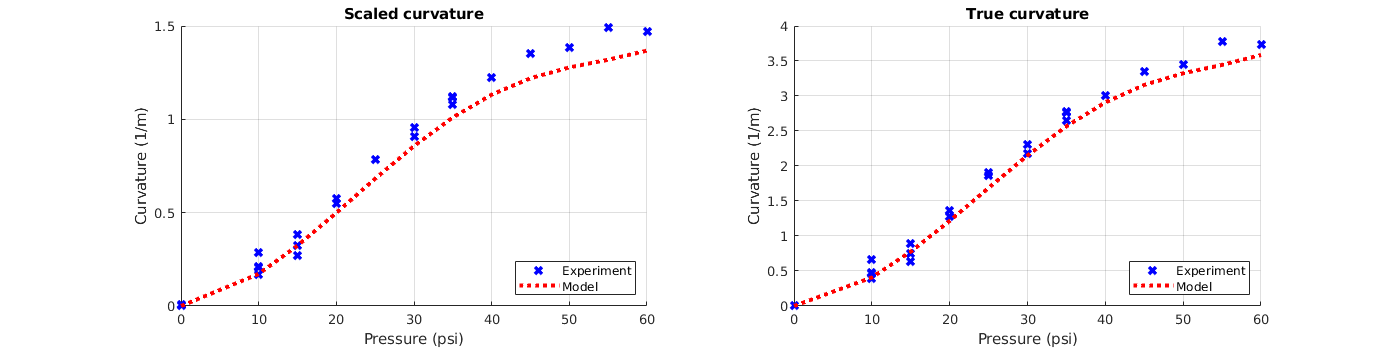

function arm_obj = create_arm_obj(width, base_offset_cm)
    arguments
        width
        base_offset_cm = 3;
    end

    % Create arm object
    g_1 = SE2.hat([0, -base_offset_cm / 100, pi/2]);
    
    rho = width/2 * 0.0254;
    g_o_1 = SE2.hat([0, rho, 0]); % Muscle 1
    g_o_2 = SE2.hat([0, -rho, 0]); % Muscle 2
    g_o = g_1 * inv(g_o_1); % Central muscle
    g_o_muscles = {g_1; g_o * g_o_2};
    l_0 = contraction_fit_poly(0);

    mat_K = diag([1, 0, 0.00020]); % Remember to use 20


    arm_obj = Arm2D(g_o, g_o_muscles, l_0, mat_K, 'plot_unstrained', false);
end